## **HCP Main Sample - Internal Cross-Validation 'Latent NMA Model'**

**Extraversion Trait-irrelevant Tasks (Emotion Task; Language Task, Motor Task, Relational Processing Task and Working Memory Task) **

Conduction of the internal cross-validation of the 'Latent NMA Model' that is built using two input predictor variables. The predictor variables are derived from individual's (latent) coupling values and extracted by using group-based positive and group-based negative NMA masks. This script contains three parts: **Part 1 **unifies the task-specific regional SC-FC coupling values into 'latent values' (either via factor analysis or PCA), partitions the sample into five different folds (considering family relations and distribution of the respective personality trait), and creates positive and negative NMAs for each training fold and test fold. **Part 2 **uses the NMAs ctreated in Part 1 to build multiple linear regression models that are then tested for their ability to predict the respective personality score in the test samples. Part 3 assesses the significance of the prediction with a permutation test. 

Before runnung this script: 

- run all scripts in HCP Data Prep

**Part 1**

Unifying task-specific regional SC-FC coupling values into 'latent values' (either via factor analyses ot PCA), partitioning the sample into 5 different folds and creating the positive and negative NMAs for each training fold and test fold based on the correlation with the respective personality trait. 

**1. Prepare the coupling data **

1.1. Emotion Task

1.1.1. Create a cell that contains for each subject a vecor of 8 predictors for each node 

for i = 1:532
    x = final_r_all_HCP_emotion_532{i,1};
    for j = 1:358
    Node_all_baseline_HCP_emotion{i,j} = x(j,:);
    end
end

1.1.2. Create cell that contains information from all subjects and all coupling measures for all nodes separetely (532*8)

% extract for each collumn 8 rows from each row and put them together in a matrix (--> I need 532*8 matrix for each node)

n = size(Node_all_baseline_HCP_emotion,2);
All_Nodes_complete_HCP_emotion = cell(1,n);
for j = 1:n
    All_Nodes_complete_HCP_emotion{j} = vertcat(Node_all_baseline_HCP_emotion{:,j});
end 

1.1.3. Only keep 4 measures: Path Length (1), Communicability (2), Cosine Distance (3), & Search Information (4)

for i = 1:358
    eight_measures_per_node = All_Nodes_complete_HCP_emotion{1,i};
    four_measures_per_node = eight_measures_per_node(:,1:4);
    All_Nodes_complete_HCP_emotion_4_measures{1,i} = four_measures_per_node;
end

1.2. Language task

1.2.1. Create a cell that contains for each subject a vecor of 8 predictors for each node 

for i = 1:532
    x = final_r_all_HCP_language_532{i,1};
    for j = 1:358
    Node_all_baseline_HCP_language{i,j} = x(j,:);
    end
end

1.2.2. Create cell that contains information from all subjects and all coupling measures for all nodes separetely (532*8)

% extract for each collumn 8 rows from each row and put them together in a matrix (--> I need 532*8 matrix for each node)

n = size(Node_all_baseline_HCP_language,2);
All_Nodes_complete_HCP_language = cell(1,n);
for j = 1:n
    All_Nodes_complete_HCP_language{j} = vertcat(Node_all_baseline_HCP_language{:,j});
end 

1.2.3. Only keep 4 measures: Path Length (1), Communicability (2), Cosine Distance (3), & Search Information (4)

for i = 1:358
    eight_measures_per_node = All_Nodes_complete_HCP_language{1,i};
    four_measures_per_node = eight_measures_per_node(:,1:4);
    All_Nodes_complete_HCP_language_4_measures{1,i} = four_measures_per_node;
end

1.3. Motor task

1.3.1. Create a cell that contains for each subject a vecor of 8 predictors for each node 

for i = 1:532
    x = final_r_all_HCP_motor_532{i,1};
    for j = 1:358
    Node_all_baseline_HCP_motor{i,j} = x(j,:);
    end
end

1.3.2. Create cell that contains information from all subjects and all coupling measures for all nodes separetely (532*8)

% extract for each collumn 8 rows from each row and put them together in a matrix (--> I need 532*8 matrix for each node)

n = size(Node_all_baseline_HCP_motor,2);
All_Nodes_complete_HCP_motor = cell(1,n);
for j = 1:n
    All_Nodes_complete_HCP_motor{j} = vertcat(Node_all_baseline_HCP_motor{:,j});
end 

1.3.3. Only keep 4 measures: Path Length (1), Communicability (2), Cosine Distance (3), & Search Information (4)

for i = 1:358
    eight_measures_per_node = All_Nodes_complete_HCP_motor{1,i};
    four_measures_per_node = eight_measures_per_node(:,1:4);
    All_Nodes_complete_HCP_motor_4_measures{1,i} = four_measures_per_node;
end

1.4. Relational Processing Task

1.4.1. Create a cell that contains for each subject a vecor of 8 predictors for each node 

for i = 1:532
    x = final_r_all_HCP_relational_532{i,1};
    for j = 1:358
    Node_all_baseline_HCP_relational{i,j} = x(j,:);
    end
end


1.4.2. Create cell that contains information from all subjects and all coupling measures for all nodes separetely (532*8)

% extract for each collumn 8 rows from each row and put them together in a matrix (--> I need 532*8 matrix for each node)

n = size(Node_all_baseline_HCP_relational,2);
All_Nodes_complete_HCP_relational = cell(1,n);
for j = 1:n
    All_Nodes_complete_HCP_relational{j} = vertcat(Node_all_baseline_HCP_relational{:,j});
end 

1.4.3. Only keep 4 measures: Path Length (1), Communicability (2), Cosine Distance (3), & Search Information (4)

for i = 1:358
    eight_measures_per_node = All_Nodes_complete_HCP_relational{1,i};
    four_measures_per_node = eight_measures_per_node(:,1:4);
    All_Nodes_complete_HCP_relational_4_measures{1,i} = four_measures_per_node;
end

1.5. Working Memory Task

1.5.1. Create a cell that contains for each subject a vecor of 8 predictors for each node 

for i = 1:532
    x = final_r_all_HCP_wm_532{i,1};
    for j = 1:358
    Node_all_baseline_HCP_wm{i,j} = x(j,:);
    end
end

1.5.2. Create cell that contains information from all subjects and all coupling measures for all nodes separetely (532*8)

% extract for each collumn 8 rows from each row and put them together in a matrix (--> I need 532*8 matrix for each node)

n = size(Node_all_baseline_HCP_wm,2);
All_Nodes_complete_HCP_wm = cell(1,n);
for j = 1:n
    All_Nodes_complete_HCP_wm{j} = vertcat(Node_all_baseline_HCP_wm{:,j});
end 

1.5.3. Only keep 4 measures: Path Length (1), Communicability (2), Cosine Distance (3), & Search Information (4)

for i = 1:358
    eight_measures_per_node = All_Nodes_complete_HCP_wm{1,i};
    four_measures_per_node = eight_measures_per_node(:,1:4);
    All_Nodes_complete_HCP_wm_4_measures{1,i} = four_measures_per_node;
end

**1.2. Create a latent factor across tasks (for each node/measure separately) **

Extract node-specific values, create a latent variable for each measure/node & bring it back into the format that we started out with. 

for i = 1:358
    

% Path Length 
emotion_PL = All_Nodes_complete_HCP_emotion_4_measures{1,i}(:,1);
language_PL = All_Nodes_complete_HCP_language_4_measures{1,i}(:,1);
motor_PL = All_Nodes_complete_HCP_motor_4_measures{1,i}(:,1);
relational_PL = All_Nodes_complete_HCP_relational_4_measures{1,i}(:,1);
wm_PL = All_Nodes_complete_HCP_wm_4_measures{1,i}(:,1);

Node_1_PL_all_values = [emotion_PL language_PL motor_PL relational_PL wm_PL];

[~, ~, ~, ~, F_PL] = factoran(Node_1_PL_all_values,1);

% Communicability 
emotion_G = All_Nodes_complete_HCP_emotion_4_measures{1,i}(:,2);
language_G = All_Nodes_complete_HCP_language_4_measures{1,i}(:,2);
motor_G = All_Nodes_complete_HCP_motor_4_measures{1,i}(:,2);
relational_G = All_Nodes_complete_HCP_relational_4_measures{1,i}(:,2);
wm_G = All_Nodes_complete_HCP_wm_4_measures{1,i}(:,2);

Node_1_G_all_values = [emotion_G language_G motor_G relational_G wm_G];

[~, ~, ~, ~, F_G] = factoran(Node_1_G_all_values,1);

% Cos
emotion_CoS = All_Nodes_complete_HCP_emotion_4_measures{1,i}(:,3);
language_CoS = All_Nodes_complete_HCP_language_4_measures{1,i}(:,3);
motor_CoS = All_Nodes_complete_HCP_motor_4_measures{1,i}(:,3);
relational_CoS = All_Nodes_complete_HCP_relational_4_measures{1,i}(:,3);
wm_CoS = All_Nodes_complete_HCP_wm_4_measures{1,i}(:,3);

Node_1_CoS_all_values = [emotion_CoS language_CoS motor_CoS relational_CoS wm_CoS];

[~, ~, ~, ~, F_CoS] = factoran(Node_1_CoS_all_values,1);

% SI 
emotion_SI = All_Nodes_complete_HCP_emotion_4_measures{1,i}(:,4);
language_SI = All_Nodes_complete_HCP_language_4_measures{1,i}(:,4);
motor_SI = All_Nodes_complete_HCP_motor_4_measures{1,i}(:,4);
relational_SI = All_Nodes_complete_HCP_relational_4_measures{1,i}(:,4);
wm_SI = All_Nodes_complete_HCP_wm_4_measures{1,i}(:,4);

Node_1_SI_all_values = [emotion_SI language_SI motor_SI relational_SI wm_SI];

[~, ~, ~, ~, F_SI] = factoran(Node_1_SI_all_values,1);

% All together 

All_Nodes_complete_HCP_latent_across_all_tasks_4_measures{1,i}(:,1) = F_PL;
All_Nodes_complete_HCP_latent_across_all_tasks_4_measures{1,i}(:,2) = F_G;
All_Nodes_complete_HCP_latent_across_all_tasks_4_measures{1,i}(:,3) = F_CoS;
All_Nodes_complete_HCP_latent_across_all_tasks_4_measures{1,i}(:,4) = F_SI;

end

**2. Split sample into 5 folds **

2.1. Create a loop to do the partition 100 times 

for cross_validation_round = 1:100
    display(cross_validation_round)

cross_validation_round = 1

cross_validation_round = 2

cross_validation_round = 3

cross_validation_round = 4

cross_validation_round = 5

cross_validation_round = 6

cross_validation_round = 7

cross_validation_round = 8

cross_validation_round = 9

cross_validation_round = 10

cross_validation_round = 11

cross_validation_round = 12

cross_validation_round = 13

cross_validation_round = 14

cross_validation_round = 15

cross_validation_round = 16

cross_validation_round = 17

cross_validation_round = 18

cross_validation_round = 19

cross_validation_round = 20

cross_validation_round = 21

cross_validation_round = 22

cross_validation_round = 23

cross_validation_round = 24

cross_validation_round = 25

cross_validation_round = 26

cross_validation_round = 27

cross_validation_round = 28

cross_validation_round = 29

cross_validation_round = 30

cross_validation_round = 31

cross_validation_round = 32

cross_validation_round = 33

cross_validation_round = 34

cross_validation_round = 35

cross_validation_round = 36

cross_validation_round = 37

cross_validation_round = 38

cross_validation_round = 39

cross_validation_round = 40

cross_validation_round = 41

cross_validation_round = 42

cross_validation_round = 43

cross_validation_round = 44

cross_validation_round = 45

cross_validation_round = 46

cross_validation_round = 47

cross_validation_round = 48

cross_validation_round = 49

cross_validation_round = 50

cross_validation_round = 51

cross_validation_round = 52

cross_validation_round = 53

cross_validation_round = 54

cross_validation_round = 55

cross_validation_round = 56

cross_validation_round = 57

cross_validation_round = 58

cross_validation_round = 59

cross_validation_round = 60

cross_validation_round = 61

cross_validation_round = 62

cross_validation_round = 63

cross_validation_round = 64

cross_validation_round = 65

cross_validation_round = 66

cross_validation_round = 67

cross_validation_round = 68

cross_validation_round = 69

cross_validation_round = 70

cross_validation_round = 71

cross_validation_round = 72

cross_validation_round = 73

cross_validation_round = 74

cross_validation_round = 75

cross_validation_round = 76

cross_validation_round = 77

cross_validation_round = 78

cross_validation_round = 79

cross_validation_round = 80

cross_validation_round = 81

cross_validation_round = 82

cross_validation_round = 83

cross_validation_round = 84

cross_validation_round = 85

cross_validation_round = 86

cross_validation_round = 87

cross_validation_round = 88

cross_validation_round = 89

cross_validation_round = 90

cross_validation_round = 91

cross_validation_round = 92

cross_validation_round = 93

cross_validation_round = 94

cross_validation_round = 95

cross_validation_round = 96

cross_validation_round = 97

cross_validation_round = 98

cross_validation_round = 99

cross_validation_round = 100

2.2. Create cross-validation partition based on family personality score

This part of the script creates a partition for the internal cross-validation of the linear regression model that is stratified based on family personality score. That way, we respect the family structures in the HCP and create a distribution of subjects in the test and training samples that is not biased towards personlity scores. 

2.2.1. Assign the variables

HCP_family_ID = HCP_behavioral_532.Family_ID;
HCP_subject_names = HCP_behavioral_532.("Subject Name");
HCP_personality_score = HCP_behavioral_532.NEOFAC_E;

2.2.2. Create a table containing all the information that I need 

[number_of_families,~,family_group_number] = unique(HCP_behavioral_532.Family_ID); 
% there are 268 families in the main main sample (unique output 1)

for i = 1:268 % because there is 268 families in the sample (unique output 1) 
    
    indices_for_same_family = find(family_group_number == i);
    subject_ID_same_fam = HCP_subject_names(indices_for_same_family);
    family_ID_original = HCP_family_ID(indices_for_same_family);
    personality_score_same_fam = HCP_personality_score(indices_for_same_family);
    
    family_info_HCP{i,1} = i;
    family_info_HCP{i,2} = family_ID_original;
    family_info_HCP{i,3} = indices_for_same_family;
    family_info_HCP{i,4} = subject_ID_same_fam;
    family_info_HCP{i,5} = personality_score_same_fam;
    
end

2.2.3. Create a family personality score

for i = 1:268
    family_personality_separate = family_info_HCP{i,5};
    family_personality_average = mean(family_personality_separate);
    family_info_HCP{i,6} = family_personality_average;
end

2.2.4. Convert cell to table

family_info_HCP_table = cell2table(family_info_HCP);
family_info_HCP_table.Properties.VariableNames = {'Group Number','Original_Family_ID', 'Indices_for_same_Family', 'Subject_ID_same_fam', 'personality_score_separate_same_fam', 'Mean_personality_score_same_fam'};

2.2.5. Create a CV partition based on family personality score (for the families) 

Family_personality = family_info_HCP_table.Mean_personality_score_same_fam;


Personality_for_cv_partition_1 = rescale(Family_personality,1,30);
Personality_for_cv_partition = int16(Personality_for_cv_partition_1); % create 30 groups to ultimatly create a stratified cv partition


c = cvpartition(Personality_for_cv_partition,'KFold',5);

2.2.6. Create output: indices for the families

% Train 1 & Test 1 

index_test_1 = find(test(c,1));
index_train_1 = find(training(c,1));

% Train 2 & Test 2 
index_test_2 = find(test(c,2));
index_train_2 = find(training(c,2));

% Train 3 & Test 3 

index_test_3 = find(test(c,3));
index_train_3 = find(training(c,3));

% Train 4 & Test 4 

index_test_4 = find(test(c,4));
index_train_4 = find(training(c,4));

% Train 5 & Test 5 

index_test_5 = find(test(c,5));
index_train_5 = find(training(c,5));


2.2.7. Reassign the individual subjects back into the groups from the partition 

% Train 1 & Test 1 

test_1 = family_info_HCP_table.Indices_for_same_Family(index_test_1);
index_test_1_fam = cat(1,test_1{:,1});
index_test_1_fam = sort(index_test_1_fam,"ascend");

train_1 = family_info_HCP_table.Indices_for_same_Family(index_train_1);
index_train_1_fam = cat(1,train_1{:,1});
index_train_1_fam = sort(index_train_1_fam,"ascend");

% Train 2 & Test 2 

test_2 = family_info_HCP_table.Indices_for_same_Family(index_test_2);
index_test_2_fam = cat(1,test_2{:,1});
index_test_2_fam = sort(index_test_2_fam,"ascend");

train_2 = family_info_HCP_table.Indices_for_same_Family(index_train_2);
index_train_2_fam = cat(1,train_2{:,1});
index_train_2_fam = sort(index_train_2_fam,"ascend");


% Train 3 & Test 3 

test_3 = family_info_HCP_table.Indices_for_same_Family(index_test_3);
index_test_3_fam = cat(1,test_3{:,1});
index_test_3_fam = sort(index_test_3_fam,"ascend");

train_3 = family_info_HCP_table.Indices_for_same_Family(index_train_3);
index_train_3_fam = cat(1,train_3{:,1});
index_train_3_fam = sort(index_train_3_fam,"ascend");


% Train 4 & Test 4 

test_4 = family_info_HCP_table.Indices_for_same_Family(index_test_4);
index_test_4_fam = cat(1,test_4{:,1});
index_test_4_fam = sort(index_test_4_fam,"ascend");

train_4 = family_info_HCP_table.Indices_for_same_Family(index_train_4);
index_train_4_fam = cat(1,train_4{:,1});
index_train_4_fam = sort(index_train_4_fam,"ascend");


% Train 5 & Test 5 

test_5 = family_info_HCP_table.Indices_for_same_Family(index_test_5);
index_test_5_fam = cat(1,test_5{:,1});
index_test_5_fam = sort(index_test_5_fam,"ascend");

train_5 = family_info_HCP_table.Indices_for_same_Family(index_train_5);
index_train_5_fam = cat(1,train_5{:,1});
index_train_5_fam = sort(index_train_5_fam,"ascend");

% done with creating the training/test partition

2.3. Divide data in test and training samples 

2.3.1.  Divide the coupling data into 5 training and 5 test samples

for i = 1:358
   all_data_node = All_Nodes_complete_HCP_latent_across_all_tasks_4_measures{1,i};
   
   Node_training_sample_1 = all_data_node(index_train_1_fam,:);
   Node_test_sample_1 = all_data_node(index_test_1_fam,:);
   
   Node_training_sample_2 = all_data_node(index_train_2_fam,:);
   Node_test_sample_2 = all_data_node(index_test_2_fam,:);
   
   Node_training_sample_3 = all_data_node(index_train_3_fam,:);
   Node_test_sample_3 = all_data_node(index_test_3_fam, :);
   
   Node_training_sample_4 = all_data_node(index_train_4_fam,:);
   Node_test_sample_4 = all_data_node(index_test_4_fam,:);
   
   Node_training_sample_5 = all_data_node(index_train_5_fam,:);
   Node_test_sample_5 = all_data_node(index_test_5_fam, :);
   
   All_Nodes_complete_cross_validation_HCP_{1,i} = Node_training_sample_1;
   All_Nodes_complete_cross_validation_HCP_{2,i} = Node_training_sample_2;
   All_Nodes_complete_cross_validation_HCP_{3,i} = Node_training_sample_3;
   All_Nodes_complete_cross_validation_HCP_{4,i} = Node_training_sample_4;
   All_Nodes_complete_cross_validation_HCP_{5,i} = Node_training_sample_5;
   All_Nodes_complete_cross_validation_HCP_{6,i} = Node_test_sample_1;
   All_Nodes_complete_cross_validation_HCP_{7,i} = Node_test_sample_2;
   All_Nodes_complete_cross_validation_HCP_{8,i} = Node_test_sample_3;
   All_Nodes_complete_cross_validation_HCP_{9,i} = Node_test_sample_4;
   All_Nodes_complete_cross_validation_HCP_{10,i} = Node_test_sample_5;
   
end

2.3.2. Divide personality into 5 training samples & 5 test samples

Personality = HCP_behavioral_532.NEOFAC_E;

Personality_train_1 = Personality(index_train_1_fam,:);
Personality_train_2 = Personality(index_train_2_fam,:);
Personality_train_3 = Personality(index_train_3_fam,:);
Personality_train_4 = Personality(index_train_4_fam,:);
Personality_train_5 = Personality(index_train_5_fam,:);

Personality_test_1 = Personality(index_test_1_fam,:);
Personality_test_2 = Personality(index_test_2_fam,:);
Personality_test_3 = Personality(index_test_3_fam,:);
Personality_test_4 = Personality(index_test_4_fam,:);
Personality_test_5 = Personality(index_test_5_fam,:);

Personality_training_samples{1,:} = Personality_train_1;
Personality_training_samples{2,:} = Personality_train_2;
Personality_training_samples{3,:} = Personality_train_3;
Personality_training_samples{4,:} = Personality_train_4;
Personality_training_samples{5,:} = Personality_train_5;

Personality_test_samples{1,:} = Personality_test_1;
Personality_test_samples{2,:} = Personality_test_2;
Personality_test_samples{3,:} = Personality_test_3;
Personality_test_samples{4,:} = Personality_test_4;
Personality_test_samples{5,:} = Personality_test_5;

2.3.3.  Divide confounding variables into 5 training samples & 5 test samples

Age = HCP_behavioral_532.Age_in_Yrs;

Age_train_1 = Age(index_train_1_fam,:);
Age_train_2 = Age(index_train_2_fam,:);
Age_train_3 = Age(index_train_3_fam,:);
Age_train_4 = Age(index_train_4_fam,:);
Age_train_5 = Age(index_train_5_fam,:);

Age_test_1 = Age(index_test_1_fam,:);
Age_test_2 = Age(index_test_2_fam,:);
Age_test_3 = Age(index_test_3_fam,:);
Age_test_4 = Age(index_test_4_fam,:);
Age_test_5 = Age(index_test_5_fam, :);


Age_training_samples{1,:} = Age_train_1;
Age_training_samples{2,:} = Age_train_2;
Age_training_samples{3,:} = Age_train_3;
Age_training_samples{4,:} = Age_train_4;
Age_training_samples{5,:} = Age_train_5;

Age_test_samples{1,:} = Age_test_1;
Age_test_samples{2,:} = Age_test_2;
Age_test_samples{3,:} = Age_test_3;
Age_test_samples{4,:} = Age_test_4;
Age_test_samples{5,:} = Age_test_5;

Gender = HCP_behavioral_532.gender_num;

Gender_train_1 = Gender(index_train_1_fam,:);
Gender_train_2 = Gender(index_train_2_fam,:);
Gender_train_3 = Gender(index_train_3_fam,:);
Gender_train_4 = Gender(index_train_4_fam,:);
Gender_train_5 = Gender(index_train_5_fam,:);

Gender_test_1 = Gender(index_test_1_fam,:);
Gender_test_2 = Gender(index_test_2_fam,:);
Gender_test_3 = Gender(index_test_3_fam,:);
Gender_test_4 = Gender(index_test_4_fam,:);
Gender_test_5 = Gender(index_test_5_fam,:);

Gender_training_samples{1,:} = Gender_train_1;
Gender_training_samples{2,:} = Gender_train_2;
Gender_training_samples{3,:} = Gender_train_3;
Gender_training_samples{4,:} = Gender_train_4;
Gender_training_samples{5,:} = Gender_train_5;

Gender_test_samples{1,:} = Gender_test_1;
Gender_test_samples{2,:} = Gender_test_2;
Gender_test_samples{3,:} = Gender_test_3;
Gender_test_samples{4,:} = Gender_test_4;
Gender_test_samples{5,:} = Gender_test_5;

meanFDJenk_emotion = HCP_behavioral_532.mean_mean_RMS_emotion;

meanFDJenk_emotion_train_1 = meanFDJenk_emotion(index_train_1_fam,:);
meanFDJenk_emotion_train_2 = meanFDJenk_emotion(index_train_2_fam,:);
meanFDJenk_emotion_train_3 = meanFDJenk_emotion(index_train_3_fam,:);
meanFDJenk_emotion_train_4 = meanFDJenk_emotion(index_train_4_fam,:);
meanFDJenk_emotion_train_5 = meanFDJenk_emotion(index_train_5_fam,:);

meanFDJenk_emotion_test_1 = meanFDJenk_emotion(index_test_1_fam,:);
meanFDJenk_emotion_test_2 = meanFDJenk_emotion(index_test_2_fam,:);
meanFDJenk_emotion_test_3 = meanFDJenk_emotion(index_test_3_fam,:);
meanFDJenk_emotion_test_4 = meanFDJenk_emotion(index_test_4_fam,:);
meanFDJenk_emotion_test_5 = meanFDJenk_emotion(index_test_5_fam,:);


meanFDJenk_emotion_training_samples{1,:} = meanFDJenk_emotion_train_1;
meanFDJenk_emotion_training_samples{2,:} = meanFDJenk_emotion_train_2;
meanFDJenk_emotion_training_samples{3,:} = meanFDJenk_emotion_train_3;
meanFDJenk_emotion_training_samples{4,:} = meanFDJenk_emotion_train_4;
meanFDJenk_emotion_training_samples{5,:} = meanFDJenk_emotion_train_5;

meanFDJenk_emotion_test_samples{1,:} = meanFDJenk_emotion_test_1;
meanFDJenk_emotion_test_samples{2,:} = meanFDJenk_emotion_test_2;
meanFDJenk_emotion_test_samples{3,:} = meanFDJenk_emotion_test_3;
meanFDJenk_emotion_test_samples{4,:} = meanFDJenk_emotion_test_4;
meanFDJenk_emotion_test_samples{5,:} = meanFDJenk_emotion_test_5;

meanFDJenk_language = HCP_behavioral_532.mean_mean_RMS_language;

meanFDJenk_language_train_1 = meanFDJenk_language(index_train_1_fam,:);
meanFDJenk_language_train_2 = meanFDJenk_language(index_train_2_fam,:);
meanFDJenk_language_train_3 = meanFDJenk_language(index_train_3_fam,:);
meanFDJenk_language_train_4 = meanFDJenk_language(index_train_4_fam,:);
meanFDJenk_language_train_5 = meanFDJenk_language(index_train_5_fam,:);

meanFDJenk_language_test_1 = meanFDJenk_language(index_test_1_fam,:);
meanFDJenk_language_test_2 = meanFDJenk_language(index_test_2_fam,:);
meanFDJenk_language_test_3 = meanFDJenk_language(index_test_3_fam,:);
meanFDJenk_language_test_4 = meanFDJenk_language(index_test_4_fam,:);
meanFDJenk_language_test_5 = meanFDJenk_language(index_test_5_fam,:);


meanFDJenk_language_training_samples{1,:} = meanFDJenk_language_train_1;
meanFDJenk_language_training_samples{2,:} = meanFDJenk_language_train_2;
meanFDJenk_language_training_samples{3,:} = meanFDJenk_language_train_3;
meanFDJenk_language_training_samples{4,:} = meanFDJenk_language_train_4;
meanFDJenk_language_training_samples{5,:} = meanFDJenk_language_train_5;

meanFDJenk_language_test_samples{1,:} = meanFDJenk_language_test_1;
meanFDJenk_language_test_samples{2,:} = meanFDJenk_language_test_2;
meanFDJenk_language_test_samples{3,:} = meanFDJenk_language_test_3;
meanFDJenk_language_test_samples{4,:} = meanFDJenk_language_test_4;
meanFDJenk_language_test_samples{5,:} = meanFDJenk_language_test_5;

meanFDJenk_motor = HCP_behavioral_532.mean_mean_RMS_motor;

meanFDJenk_motor_train_1 = meanFDJenk_motor(index_train_1_fam,:);
meanFDJenk_motor_train_2 = meanFDJenk_motor(index_train_2_fam,:);
meanFDJenk_motor_train_3 = meanFDJenk_motor(index_train_3_fam,:);
meanFDJenk_motor_train_4 = meanFDJenk_motor(index_train_4_fam,:);
meanFDJenk_motor_train_5 = meanFDJenk_motor(index_train_5_fam,:);

meanFDJenk_motor_test_1 = meanFDJenk_motor(index_test_1_fam,:);
meanFDJenk_motor_test_2 = meanFDJenk_motor(index_test_2_fam,:);
meanFDJenk_motor_test_3 = meanFDJenk_motor(index_test_3_fam,:);
meanFDJenk_motor_test_4 = meanFDJenk_motor(index_test_4_fam,:);
meanFDJenk_motor_test_5 = meanFDJenk_motor(index_test_5_fam,:);


meanFDJenk_motor_training_samples{1,:} = meanFDJenk_motor_train_1;
meanFDJenk_motor_training_samples{2,:} = meanFDJenk_motor_train_2;
meanFDJenk_motor_training_samples{3,:} = meanFDJenk_motor_train_3;
meanFDJenk_motor_training_samples{4,:} = meanFDJenk_motor_train_4;
meanFDJenk_motor_training_samples{5,:} = meanFDJenk_motor_train_5;

meanFDJenk_motor_test_samples{1,:} = meanFDJenk_motor_test_1;
meanFDJenk_motor_test_samples{2,:} = meanFDJenk_motor_test_2;
meanFDJenk_motor_test_samples{3,:} = meanFDJenk_motor_test_3;
meanFDJenk_motor_test_samples{4,:} = meanFDJenk_motor_test_4;
meanFDJenk_motor_test_samples{5,:} = meanFDJenk_motor_test_5;

meanFDJenk_relational = HCP_behavioral_532.mean_mean_RMS_relational;

meanFDJenk_relational_train_1 = meanFDJenk_relational(index_train_1_fam,:);
meanFDJenk_relational_train_2 = meanFDJenk_relational(index_train_2_fam,:);
meanFDJenk_relational_train_3 = meanFDJenk_relational(index_train_3_fam,:);
meanFDJenk_relational_train_4 = meanFDJenk_relational(index_train_4_fam,:);
meanFDJenk_relational_train_5 = meanFDJenk_relational(index_train_5_fam,:);

meanFDJenk_relational_test_1 = meanFDJenk_relational(index_test_1_fam,:);
meanFDJenk_relational_test_2 = meanFDJenk_relational(index_test_2_fam,:);
meanFDJenk_relational_test_3 = meanFDJenk_relational(index_test_3_fam,:);
meanFDJenk_relational_test_4 = meanFDJenk_relational(index_test_4_fam,:);
meanFDJenk_relational_test_5 = meanFDJenk_relational(index_test_5_fam,:);


meanFDJenk_relational_training_samples{1,:} = meanFDJenk_relational_train_1;
meanFDJenk_relational_training_samples{2,:} = meanFDJenk_relational_train_2;
meanFDJenk_relational_training_samples{3,:} = meanFDJenk_relational_train_3;
meanFDJenk_relational_training_samples{4,:} = meanFDJenk_relational_train_4;
meanFDJenk_relational_training_samples{5,:} = meanFDJenk_relational_train_5;

meanFDJenk_relational_test_samples{1,:} = meanFDJenk_relational_test_1;
meanFDJenk_relational_test_samples{2,:} = meanFDJenk_relational_test_2;
meanFDJenk_relational_test_samples{3,:} = meanFDJenk_relational_test_3;
meanFDJenk_relational_test_samples{4,:} = meanFDJenk_relational_test_4;
meanFDJenk_relational_test_samples{5,:} = meanFDJenk_relational_test_5;

meanFDJenk_wm = HCP_behavioral_532.mean_mean_RMS_wm;

meanFDJenk_wm_train_1 = meanFDJenk_wm(index_train_1_fam,:);
meanFDJenk_wm_train_2 = meanFDJenk_wm(index_train_2_fam,:);
meanFDJenk_wm_train_3 = meanFDJenk_wm(index_train_3_fam,:);
meanFDJenk_wm_train_4 = meanFDJenk_wm(index_train_4_fam,:);
meanFDJenk_wm_train_5 = meanFDJenk_wm(index_train_5_fam,:);

meanFDJenk_wm_test_1 = meanFDJenk_wm(index_test_1_fam,:);
meanFDJenk_wm_test_2 = meanFDJenk_wm(index_test_2_fam,:);
meanFDJenk_wm_test_3 = meanFDJenk_wm(index_test_3_fam,:);
meanFDJenk_wm_test_4 = meanFDJenk_wm(index_test_4_fam,:);
meanFDJenk_wm_test_5 = meanFDJenk_wm(index_test_5_fam,:);


meanFDJenk_wm_training_samples{1,:} = meanFDJenk_wm_train_1;
meanFDJenk_wm_training_samples{2,:} = meanFDJenk_wm_train_2;
meanFDJenk_wm_training_samples{3,:} = meanFDJenk_wm_train_3;
meanFDJenk_wm_training_samples{4,:} = meanFDJenk_wm_train_4;
meanFDJenk_wm_training_samples{5,:} = meanFDJenk_wm_train_5;

meanFDJenk_wm_test_samples{1,:} = meanFDJenk_wm_test_1;
meanFDJenk_wm_test_samples{2,:} = meanFDJenk_wm_test_2;
meanFDJenk_wm_test_samples{3,:} = meanFDJenk_wm_test_3;
meanFDJenk_wm_test_samples{4,:} = meanFDJenk_wm_test_4;
meanFDJenk_wm_test_samples{5,:} = meanFDJenk_wm_test_5;

LQ = HCP_behavioral_532.Handedness;

LQ_train_1 = LQ(index_train_1_fam,:);
LQ_train_2 = LQ(index_train_2_fam,:);
LQ_train_3 = LQ(index_train_3_fam,:);
LQ_train_4 = LQ(index_train_4_fam,:);
LQ_train_5 = LQ(index_train_5_fam,:);

LQ_test_1 = LQ(index_test_1_fam,:);
LQ_test_2 = LQ(index_test_2_fam,:);
LQ_test_3 = LQ(index_test_3_fam,:);
LQ_test_4 = LQ(index_test_4_fam,:);
LQ_test_5 = LQ(index_test_5_fam,:);


LQ_training_samples{1,:} = LQ_train_1;
LQ_training_samples{2,:} = LQ_train_2;
LQ_training_samples{3,:} = LQ_train_3;
LQ_training_samples{4,:} = LQ_train_4;
LQ_training_samples{5,:} = LQ_train_5;

LQ_test_samples{1,:} = LQ_test_1;
LQ_test_samples{2,:} = LQ_test_2;
LQ_test_samples{3,:} = LQ_test_3;
LQ_test_samples{4,:} = LQ_test_4;
LQ_test_samples{5,:} = LQ_test_5;

2.4. Build a positive and negative node measure assignment (NMA) for each training sample

2.4.1. Build a correlation matrix for each training fold 

for fold = 1:5
    
Correlation_com_measures_fold_rho = zeros(358,4); % Preallocation
Correlation_com_measure_fold_pval = zeros(358,4); % Preallocation
    
for i = 1:358 
    All_Communication_measures_per_node = All_Nodes_complete_cross_validation_HCP_{fold,i};
    
     for p = 1:4 % jetzt jedes communication measure mit Personality korrelieren
        Communication_Measure_separate = All_Communication_measures_per_node(:,p);
        
             % Correlation

                x = [Communication_Measure_separate, Personality_training_samples{fold}];
                z = [Age_training_samples{fold}, Gender_training_samples{fold}, meanFDJenk_emotion_training_samples{fold}, meanFDJenk_language_training_samples{fold}, meanFDJenk_motor_training_samples{fold}, meanFDJenk_relational_training_samples{fold},meanFDJenk_wm_training_samples{fold}, LQ_training_samples{fold}]; % control variables
   
                [rho,pval] = partialcorr(x,z);
                
                rho = rho(1,2);
                pval = pval(1,2);
            
               Correlation_com_measures_fold_rho(i,p) = rho;
               Correlation_com_measure_fold_pval(i,p) = pval;

               
    end
end

Correlation_matrices_all_folds{fold,1} = Correlation_com_measures_fold_rho;
Correlation_matrices_all_folds{fold,2} = Correlation_com_measure_fold_pval;
end

2.4.2. Find out which ones correlate most positive with personality trait

for fold = 1:5
    Correlation_com_measures_fold_rho = Correlation_matrices_all_folds{fold,1};
for i = 1:358
    Correlation_rho_per_node = Correlation_com_measures_fold_rho(i,:);
    Max_Rho = max(Correlation_rho_per_node);
    Idx_max_rho = find(Correlation_rho_per_node == Max_Rho);
    Info_best_performing_communication_measure_pos_train_rho{i,1} = Max_Rho;
    Info_best_performing_communication_measure_pos_train_idx{i,1} = Idx_max_rho;
end
Pos_NMA_all_fold{fold,1} = Info_best_performing_communication_measure_pos_train_rho;
Pos_NMA_all_fold{fold,2} = Info_best_performing_communication_measure_pos_train_idx;
end

2.4.3. Find out which ones correlate the most negative with personality trait

for fold = 1:5
    Correlation_com_measures_fold_rho = Correlation_matrices_all_folds{fold,1};

for i = 1:358
    Correlation_rho_per_node = Correlation_com_measures_fold_rho(i,:);
    Min_Rho = min(Correlation_rho_per_node);
    Idx_min_rho = find(Correlation_rho_per_node == Min_Rho);
    Info_best_performing_communication_measure_neg_train_rho{i,1} = Min_Rho;
    Info_best_performing_communication_measure_neg_train_idx{i,1} = Idx_min_rho;
end
Neg_NMA_all_fold{fold,1} = Info_best_performing_communication_measure_neg_train_rho;
Neg_NMA_all_fold{fold,2} = Info_best_performing_communication_measure_neg_train_idx;
end

2.4.4. Define sizes of training samples and test samples 

size_training_sample_1 = size(All_Nodes_complete_cross_validation_HCP_{1,1},1);
size_training_sample_2 = size(All_Nodes_complete_cross_validation_HCP_{2,1},1);
size_training_sample_3 = size(All_Nodes_complete_cross_validation_HCP_{3,1},1);
size_training_sample_4 = size(All_Nodes_complete_cross_validation_HCP_{4,1},1);
size_training_sample_5 = size(All_Nodes_complete_cross_validation_HCP_{5,1},1);

size_test_sample_1 = size(All_Nodes_complete_cross_validation_HCP_{6,1},1);
size_test_sample_2 = size(All_Nodes_complete_cross_validation_HCP_{7,1},1);
size_test_sample_3 = size(All_Nodes_complete_cross_validation_HCP_{8,1},1);
size_test_sample_4 = size(All_Nodes_complete_cross_validation_HCP_{9,1},1);
size_test_sample_5 = size(All_Nodes_complete_cross_validation_HCP_{10,1},1);

size_training_test_samples{1,1} = size_training_sample_1;
size_training_test_samples{2,1} = size_training_sample_2;
size_training_test_samples{3,1} = size_training_sample_3;
size_training_test_samples{4,1} = size_training_sample_4;
size_training_test_samples{5,1} = size_training_sample_5;

size_training_test_samples{1,2} = size_test_sample_1;
size_training_test_samples{2,2} = size_test_sample_2;
size_training_test_samples{3,2} = size_test_sample_3;
size_training_test_samples{4,2} = size_test_sample_4;
size_training_test_samples{5,2} = size_test_sample_5; 

2.4.5. Extract the NMA values for the positive NMA

for fold = 1:5

size_sample = size_training_test_samples{fold,1};     
Best_case_scenario_r_values_pos_train = zeros(358,size_sample);
best_performing_measure_per_node_pos = cell2mat(Pos_NMA_all_fold{fold,2});

for i = 1:358
    index = best_performing_measure_per_node_pos(i);
    Best_scenario_node_values_pos = All_Nodes_complete_cross_validation_HCP_{fold,i}(:,index); 
    Best_case_scenario_r_values_pos_train(i,:) = Best_scenario_node_values_pos';
end

Best_case_scenario_r_values_pos_train = Best_case_scenario_r_values_pos_train';

Best_case_scenario_training_samples{fold,1} = Best_case_scenario_r_values_pos_train;

end 

2.4.6. Extract the NMA values for the negative NMA

for fold = 1:5
   
size_sample = size_training_test_samples{fold,1};
Best_case_scenario_r_values_neg_train = zeros(358,size_sample);
best_performing_measure_per_node_neg = cell2mat(Neg_NMA_all_fold{fold,2});

for i = 1:358
    index = best_performing_measure_per_node_neg(i);
    Best_scenario_node_values_neg = All_Nodes_complete_cross_validation_HCP_{fold,i}(:,index);
    Best_case_scenario_r_values_neg_train(i,:) = Best_scenario_node_values_neg';
end

Best_case_scenario_r_values_neg_train = Best_case_scenario_r_values_neg_train';

Best_case_scenario_training_samples{fold,2} = Best_case_scenario_r_values_neg_train;

end 

2.5. Build a positive and negative node measure assignment (NMA) for each test sample

2.5.1. Extract the NMA values for the positive NMA

for fold = 1:5
    size_sample = size_training_test_samples{fold,2};
    Best_case_scenario_r_values_pos_test = zeros(358,size_sample);
    best_performing_measure_per_node_pos = cell2mat(Pos_NMA_all_fold{fold,2});
    index_into_crossvall = fold+5;

for i = 1:358 
    index = best_performing_measure_per_node_pos(i);
    Best_scenario_node_values_pos = All_Nodes_complete_cross_validation_HCP_{index_into_crossvall,i}(:,index);
    Best_case_scenario_r_values_pos_test(i,:) = Best_scenario_node_values_pos';
end

Best_case_scenario_r_values_pos_test = Best_case_scenario_r_values_pos_test';

Best_case_scenario_test_samples{fold,1} = Best_case_scenario_r_values_pos_test;

end

2.5.2. Extract the NMA values for the negative NMA

for fold = 1:5
    size_sample = size_training_test_samples{fold,2};
    Best_case_scenario_r_values_neg_test = zeros(358,size_sample);
    best_performing_measure_per_node_neg = cell2mat(Neg_NMA_all_fold{fold,2});
    index_into_crossvall = fold+5;

for i = 1:358 
    index = best_performing_measure_per_node_neg(i);
    Best_scenario_node_values_neg = All_Nodes_complete_cross_validation_HCP_{index_into_crossvall,i}(:,index);
    Best_case_scenario_r_values_neg_test(i,:) = Best_scenario_node_values_neg';
end

Best_case_scenario_r_values_neg_test = Best_case_scenario_r_values_neg_test';

Best_case_scenario_test_samples{fold,2} = Best_case_scenario_r_values_neg_test;

end



**Part 2: **

Use Node-Measure Assignments created above to build multiple linear regression model in training samples and test it in test samples. 

**1. Build the Models for the Training Samples **

1.1. Training Sample 1

Regress out the confounding variables from personality and normalize the residuals 

confounds = [Age_train_1 Gender_train_1 meanFDJenk_emotion_train_1 meanFDJenk_language_train_1 meanFDJenk_motor_train_1 meanFDJenk_relational_train_1 meanFDJenk_wm_train_1 LQ_train_1];

mdl_regress_train_1_personality = fitlm(confounds,Personality_train_1);
residuals_personality_train_1 = mdl_regress_train_1_personality.Residuals.Raw;

[residuals_personality_train_1_z,c_personality_train_1,s_personality_train_1] = normalize(residuals_personality_train_1);

Retrieve NMA for the subjects

Best_case_scenario_r_values_pos = Best_case_scenario_training_samples{1,1};
Best_case_scenario_r_values_neg = Best_case_scenario_training_samples{1,2};

Take the mean per subject 

Positive_all = nanmean(Best_case_scenario_r_values_pos,2);
Negative_all = nanmean(Best_case_scenario_r_values_neg,2);

Regress out the confounding variables from positive and negative NMA and normalize the residuals

confounds = [Age_train_1 Gender_train_1 meanFDJenk_emotion_train_1 meanFDJenk_language_train_1 meanFDJenk_motor_train_1 meanFDJenk_relational_train_1 meanFDJenk_wm_train_1 LQ_train_1];

mdl_regress_train_1_pos_bcs = fitlm(confounds,Positive_all);
residuals_pos_train_1 = mdl_regress_train_1_pos_bcs.Residuals.Raw;

[residuals_pos_train_1_z, c_pos_NMA_train_1, s_pos_NMA_train_1] = normalize(residuals_pos_train_1);

mdl_regress_train_1_neg_bcs = fitlm(confounds,Negative_all);
residuals_neg_train_1 = mdl_regress_train_1_neg_bcs.Residuals.Raw;

[residuals_neg_train_1_z, c_neg_NMA_train_1, s_neg_NMA_train_1] = normalize(residuals_neg_train_1);

Build the actual model

Model_Matrix = [residuals_pos_train_1_z residuals_neg_train_1_z residuals_personality_train_1_z];
Model_Matrix = num2cell(Model_Matrix);
Model_Matrix_table = cell2table(Model_Matrix);
Model_Matrix_table.Properties.VariableNames = {'residuals_pos_train_1_z','residuals_neg_train_1_z','Residuals_personality_train_1_z'};

mdl_pos_neg_bcs_train_1 = fitlm(Model_Matrix_table);
plot(mdl_pos_neg_bcs_train_1);

1.2. Training Sample 2

Regress out the confounding variables from personality and normalize the residuals 

confounds = [Age_train_2 Gender_train_2 meanFDJenk_emotion_train_2 meanFDJenk_language_train_2 meanFDJenk_motor_train_2 meanFDJenk_relational_train_2 meanFDJenk_wm_train_2 LQ_train_2];

mdl_regress_train_2_personality = fitlm(confounds,Personality_train_2);
residuals_personality_train_2 = mdl_regress_train_2_personality.Residuals.Raw;

[residuals_personality_train_2_z,c_personality_train_2,s_personality_train_2] = normalize(residuals_personality_train_2);

Retrieve NMA for the subjects

Best_case_scenario_r_values_pos = Best_case_scenario_training_samples{2,1};
Best_case_scenario_r_values_neg = Best_case_scenario_training_samples{2,2};

Take the mean per subject

Positive_all = nanmean(Best_case_scenario_r_values_pos,2);
Negative_all = nanmean(Best_case_scenario_r_values_neg,2);

Regress out the confounding variables from positive and negative NMA and normalize the residuals

confounds = [Age_train_2 Gender_train_2 meanFDJenk_emotion_train_2 meanFDJenk_language_train_2 meanFDJenk_motor_train_2 meanFDJenk_relational_train_2 meanFDJenk_wm_train_2 LQ_train_2];

mdl_regress_train_2_pos_bcs = fitlm(confounds,Positive_all);
residuals_pos_train_2 = mdl_regress_train_2_pos_bcs.Residuals.Raw;

[residuals_pos_train_2_z, c_pos_NMA_train_2, s_pos_NMA_train_2] = normalize(residuals_pos_train_2);

mdl_regress_train_2_neg_bcs = fitlm(confounds,Negative_all);
residuals_neg_train_2 = mdl_regress_train_2_neg_bcs.Residuals.Raw;

[residuals_neg_train_2_z, c_neg_NMA_train_2, s_neg_NMA_train_2] = normalize(residuals_neg_train_2);

Build the actual model

Model_Matrix = [residuals_pos_train_2_z residuals_neg_train_2_z residuals_personality_train_2_z];
Model_Matrix = num2cell(Model_Matrix);
Model_Matrix_table = cell2table(Model_Matrix);
Model_Matrix_table.Properties.VariableNames = {'residuals_pos_train_2_z','residuals_neg_train_1_z','Residuals_personality_train_2_z'};

mdl_pos_neg_bcs_train_2 = fitlm(Model_Matrix_table);
plot(mdl_pos_neg_bcs_train_2);

1.3. Training Sample 3

Regress out the confounding variables from personality and normalize the residuals 

confounds = [Age_train_3 Gender_train_3 meanFDJenk_emotion_train_3 meanFDJenk_language_train_3 meanFDJenk_motor_train_3 meanFDJenk_relational_train_3 meanFDJenk_wm_train_3 LQ_train_3];

mdl_regress_train_3_personality = fitlm(confounds,Personality_train_3);
residuals_personality_train_3 = mdl_regress_train_3_personality.Residuals.Raw;

[residuals_personality_train_3_z,c_personality_train_3,s_personality_train_3] = normalize(residuals_personality_train_3);

Retrieve NMA for the subjects 

Best_case_scenario_r_values_pos = Best_case_scenario_training_samples{3,1};
Best_case_scenario_r_values_neg = Best_case_scenario_training_samples{3,2};

Take the mean per subject

Positive_all = nanmean(Best_case_scenario_r_values_pos,2);
Negative_all = nanmean(Best_case_scenario_r_values_neg,2);

Regress out the confounding variables from positive and negative NMA and normalize the residuals

confounds = [Age_train_3 Gender_train_3 meanFDJenk_emotion_train_3 meanFDJenk_language_train_3 meanFDJenk_motor_train_3 meanFDJenk_relational_train_3 meanFDJenk_wm_train_3 LQ_train_3];

mdl_regress_train_3_pos_bcs = fitlm(confounds,Positive_all);
residuals_pos_train_3 = mdl_regress_train_3_pos_bcs.Residuals.Raw;

[residuals_pos_train_3_z, c_pos_NMA_train_3, s_pos_NMA_train_3] = normalize(residuals_pos_train_3);

mdl_regress_train_3_neg_bcs = fitlm(confounds,Negative_all);
residuals_neg_train_3 = mdl_regress_train_3_neg_bcs.Residuals.Raw;

[residuals_neg_train_3_z, c_neg_NMA_train_3, s_neg_NMA_train_3] = normalize(residuals_neg_train_3);

Build the actual model

Model_Matrix = [residuals_pos_train_3_z residuals_neg_train_3_z residuals_personality_train_3_z];
Model_Matrix = num2cell(Model_Matrix);
Model_Matrix_table = cell2table(Model_Matrix);
Model_Matrix_table.Properties.VariableNames = {'residuals_pos_train_3_z', 'residuals_neg_train_3_z','Residuals_personality_train_3_z'};

mdl_pos_neg_bcs_train_3 = fitlm(Model_Matrix_table);
plot(mdl_pos_neg_bcs_train_3);

1.4. Training Sample 4

Regress out the confounding variables from personality and normalize the residuals

confounds = [Age_train_4 Gender_train_4 meanFDJenk_emotion_train_4 meanFDJenk_language_train_4 meanFDJenk_motor_train_4 meanFDJenk_relational_train_4 meanFDJenk_wm_train_4 LQ_train_4];

mdl_regress_train_4_personality = fitlm(confounds,Personality_train_4);
residuals_personality_train_4 = mdl_regress_train_4_personality.Residuals.Raw;

[residuals_personality_train_4_z,c_personality_train_4,s_personality_train_4] = normalize(residuals_personality_train_4);

Retrieve NMA for the subjects

Best_case_scenario_r_values_pos = Best_case_scenario_training_samples{4,1};
Best_case_scenario_r_values_neg = Best_case_scenario_training_samples{4,2};

Take the mean per subject

Positive_all = nanmean(Best_case_scenario_r_values_pos,2);
Negative_all = nanmean(Best_case_scenario_r_values_neg,2);

Regress out the confounding variables from positive and negative NMA and normalize the residuals

confounds = [Age_train_4 Gender_train_4 meanFDJenk_emotion_train_4 meanFDJenk_language_train_4 meanFDJenk_motor_train_4 meanFDJenk_relational_train_4 meanFDJenk_wm_train_4 LQ_train_4];

mdl_regress_train_4_pos_bcs = fitlm(confounds,Positive_all);
residuals_pos_train_4 = mdl_regress_train_4_pos_bcs.Residuals.Raw;

[residuals_pos_train_4_z, c_pos_NMA_train_4, s_pos_NMA_train_4] = normalize(residuals_pos_train_4);

mdl_regress_train_4_neg_bcs = fitlm(confounds,Negative_all);
residuals_neg_train_4 = mdl_regress_train_4_neg_bcs.Residuals.Raw;

[residuals_neg_train_4_z, c_neg_NMA_train_4, s_neg_NMA_train_4] = normalize(residuals_neg_train_4);

Build the actual model

Model_Matrix = [residuals_pos_train_4_z residuals_neg_train_4_z residuals_personality_train_4_z];
Model_Matrix = num2cell(Model_Matrix);
Model_Matrix_table = cell2table(Model_Matrix);
Model_Matrix_table.Properties.VariableNames = {'residuals_pos_train_4_z', 'residuals_neg_train_4_z','Residuals_personality_train_4_z'};

mdl_pos_neg_bcs_train_4 = fitlm(Model_Matrix_table);
plot(mdl_pos_neg_bcs_train_4);

1.5. Training Sample 5

Regress out the confounding variables from personality and normalize the residuals 

confounds = [Age_train_5 Gender_train_5 meanFDJenk_emotion_train_5 meanFDJenk_language_train_5 meanFDJenk_motor_train_5 meanFDJenk_relational_train_5 meanFDJenk_wm_train_5 LQ_train_5];

mdl_regress_train_5_personality = fitlm(confounds,Personality_train_5);
residuals_personality_train_5 = mdl_regress_train_5_personality.Residuals.Raw;

[residuals_personality_train_5_z,c_personality_train_5,s_personality_train_5] = normalize(residuals_personality_train_5);

Retrieve NMA for the subjects

Best_case_scenario_r_values_pos = Best_case_scenario_training_samples{5,1};
Best_case_scenario_r_values_neg = Best_case_scenario_training_samples{5,2};

Take the mean per subject

Positive_all = nanmean(Best_case_scenario_r_values_pos,2);
Negative_all = nanmean(Best_case_scenario_r_values_neg,2);

Positive_all = normalize(Positive_all);
Negative_all = normalize(Negative_all);

Regress out the confounding variables from positive and negative NMA and normalize the residuals 

confounds = [Age_train_5 Gender_train_5 meanFDJenk_emotion_train_5 meanFDJenk_language_train_5  meanFDJenk_motor_train_5 meanFDJenk_relational_train_5 meanFDJenk_wm_train_5 LQ_train_5];

mdl_regress_train_5_pos_bcs = fitlm(confounds,Positive_all);
residuals_pos_train_5 = mdl_regress_train_5_pos_bcs.Residuals.Raw;

[residuals_pos_train_5_z, c_pos_NMA_train_5, s_pos_NMA_train_5] = normalize(residuals_pos_train_5);

mdl_regress_train_5_neg_bcs = fitlm(confounds,Negative_all);
residuals_neg_train_5 = mdl_regress_train_5_neg_bcs.Residuals.Raw;

[residuals_neg_train_5_z, c_neg_NMA_train_5, s_neg_NMA_train_5] = normalize(residuals_neg_train_5);

Build the actual model

Model_Matrix = [residuals_pos_train_5_z residuals_neg_train_5_z residuals_personality_train_5_z];
Model_Matrix = num2cell(Model_Matrix);
Model_Matrix_table = cell2table(Model_Matrix);
Model_Matrix_table.Properties.VariableNames = {'residuals_pos_train_5_z', 'residuals_neg_train_5_z','Residuals_personality_train_5_z'};

mdl_pos_neg_bcs_train_5 = fitlm(Model_Matrix_table);
plot(mdl_pos_neg_bcs_train_5);

**2. Predict the personality scores in the test samples **

2.1. Test Sample 1 

Get the raw residuals by subtracting the fitted values from the observed values (using regression model from above)

confounds = [Age_test_1 Gender_test_1 meanFDJenk_emotion_test_1 meanFDJenk_language_test_1 meanFDJenk_motor_test_1 meanFDJenk_relational_test_1 meanFDJenk_wm_test_1 LQ_test_1];
personality_pred_test_1 = predict(mdl_regress_train_1_personality,confounds);

residuals_personality_test_1 = (Personality_test_1 - personality_pred_test_1);
residuals_personality_test_1_z = normalize(residuals_personality_test_1,"center",c_personality_train_1,"scale",s_personality_train_1);

Retrieve NMA for the subjects

Best_case_scenario_r_values_pos = Best_case_scenario_test_samples{1,1};
Best_case_scenario_r_values_neg = Best_case_scenario_test_samples{1,2};

Take the mean per subject

Positive_all = nanmean(Best_case_scenario_r_values_pos,2);
Negative_all = nanmean(Best_case_scenario_r_values_neg,2);

Regress out the confounding variables from positive and negative NMA and normalize the residuals 

confounds = [Age_test_1 Gender_test_1 meanFDJenk_emotion_test_1 meanFDJenk_language_test_1 meanFDJenk_motor_test_1 meanFDJenk_relational_test_1 meanFDJenk_wm_test_1 LQ_test_1];


Positive_all_pred_test_1 = predict(mdl_regress_train_1_pos_bcs,confounds);

residuals_pos_test_1 = (Positive_all - Positive_all_pred_test_1);
residuals_pos_test_1_z = normalize(residuals_pos_test_1,"center",c_pos_NMA_train_1,"scale",s_pos_NMA_train_1);


Negative_all_pred_test_1 = predict(mdl_regress_train_1_neg_bcs,confounds);

residuals_neg_test_1 = (Negative_all - Negative_all_pred_test_1);
residuals_neg_test_1_z = normalize(residuals_neg_test_1,"center",c_neg_NMA_train_1,"scale",s_neg_NMA_train_1);

Xnew = [residuals_pos_test_1_z residuals_neg_test_1_z];
ypred1_whole_sample = predict(mdl_pos_neg_bcs_train_1,Xnew);

[r,pval] = corr(ypred1_whole_sample,residuals_personality_test_1_z);

2.2. Test Sample 2 

Get the raw residuals by subtracting the fitted values from the observed values (using regression model from above)

confounds = [Age_test_2 Gender_test_2 meanFDJenk_emotion_test_2 meanFDJenk_language_test_2 meanFDJenk_motor_test_2 meanFDJenk_relational_test_2 meanFDJenk_wm_test_2 LQ_test_2];
personality_pred_test_2 = predict(mdl_regress_train_2_personality,confounds);

residuals_personality_test_2 = (Personality_test_2 - personality_pred_test_2);
residuals_personality_test_2_z = normalize(residuals_personality_test_2,"center",c_personality_train_2,"scale",s_personality_train_2);

Retrieve NMA for the subjects

Best_case_scenario_r_values_pos = Best_case_scenario_test_samples{2,1};
Best_case_scenario_r_values_neg = Best_case_scenario_test_samples{2,2};

Take the mean per subject

Positive_all = nanmean(Best_case_scenario_r_values_pos,2);
Negative_all = nanmean(Best_case_scenario_r_values_neg,2);

Regress out the confounding variables from positive and negative NMA and normalize the residuals 

confounds = [Age_test_2 Gender_test_2 meanFDJenk_emotion_test_2 meanFDJenk_language_test_2 meanFDJenk_motor_test_2 meanFDJenk_relational_test_2 meanFDJenk_wm_test_2 LQ_test_2];

Positive_all_pred_test_2 = predict(mdl_regress_train_2_pos_bcs,confounds);

residuals_pos_test_2 = (Positive_all - Positive_all_pred_test_2);
residuals_pos_test_2_z = normalize(residuals_pos_test_2,"center",c_pos_NMA_train_2,"scale",s_pos_NMA_train_2);

Negative_all_pred_test_2 = predict(mdl_regress_train_2_neg_bcs,confounds);

residuals_neg_test_2 = (Negative_all - Negative_all_pred_test_2);
residuals_neg_test_2_z = normalize(residuals_neg_test_2,"center",c_neg_NMA_train_2,"scale",s_neg_NMA_train_2);

Xnew = [residuals_pos_test_2_z residuals_neg_test_2_z];
ypred2_whole_sample = predict(mdl_pos_neg_bcs_train_2,Xnew);

[r,pval] = corr(ypred2_whole_sample,residuals_personality_test_2_z);

2.3. Test Sample 3 

Get the raw residuals by subtracting the fitted values from the observed values (using regression model from above)

confounds = [Age_test_3 Gender_test_3 meanFDJenk_emotion_test_3 meanFDJenk_language_test_3 meanFDJenk_motor_test_3 meanFDJenk_relational_test_3 meanFDJenk_wm_test_3 LQ_test_3];
personality_pred_test_3 = predict(mdl_regress_train_3_personality,confounds);

residuals_personality_test_3 = (Personality_test_3 - personality_pred_test_3);
residuals_personality_test_3_z = normalize(residuals_personality_test_3,"center",c_personality_train_3,"scale",s_personality_train_3);

Retrieve NMA for the subjects

Best_case_scenario_r_values_pos = Best_case_scenario_test_samples{3,1};
Best_case_scenario_r_values_neg = Best_case_scenario_test_samples{3,2};

Take the mean per subject

Positive_all = nanmean(Best_case_scenario_r_values_pos,2);
Negative_all = nanmean(Best_case_scenario_r_values_neg,2);

Regress out the confounding variables from positive and negative NMA and normalize the residuals 

confounds = [Age_test_3 Gender_test_3 meanFDJenk_emotion_test_3 meanFDJenk_language_test_3 meanFDJenk_motor_test_3 meanFDJenk_relational_test_3 meanFDJenk_wm_test_3 LQ_test_3];

Positive_all_pred_test_3 = predict(mdl_regress_train_3_pos_bcs,confounds);

residuals_pos_test_3 = (Positive_all - Positive_all_pred_test_3);
residuals_pos_test_3_z = normalize(residuals_pos_test_3,"center",c_pos_NMA_train_3,"scale",s_pos_NMA_train_3);

Negative_all_pred_test_3 = predict(mdl_regress_train_3_neg_bcs,confounds);

residuals_neg_test_3 = (Negative_all - Negative_all_pred_test_3);
residuals_neg_test_3_z = normalize(residuals_neg_test_3,"center",c_neg_NMA_train_3,"scale",s_neg_NMA_train_3);

Xnew = [residuals_pos_test_3_z residuals_neg_test_3_z];
ypred3_whole_sample = predict(mdl_pos_neg_bcs_train_3,Xnew);

[r,pval] = corr(ypred3_whole_sample,residuals_personality_test_3_z);

2.4. Test Sample 4 

Get the raw residuals by subtracting the fitted values from the observed values (using regresion model from above)

confounds = [Age_test_4 Gender_test_4 meanFDJenk_emotion_test_4 meanFDJenk_language_test_4 meanFDJenk_motor_test_4 meanFDJenk_relational_test_4 meanFDJenk_wm_test_4 LQ_test_4];
personality_pred_test_4 = predict(mdl_regress_train_4_personality,confounds);

residuals_personality_test_4 = (Personality_test_4 - personality_pred_test_4);
residuals_personality_test_4_z = normalize(residuals_personality_test_4,"center",c_personality_train_4,"scale",s_personality_train_4);

Retrieve NMA for the subjects

Best_case_scenario_r_values_pos = Best_case_scenario_test_samples{4,1};
Best_case_scenario_r_values_neg = Best_case_scenario_test_samples{4,2};

Take the mean per subject

Positive_all = nanmean(Best_case_scenario_r_values_pos,2);
Negative_all = nanmean(Best_case_scenario_r_values_neg,2);

Regress out the confounding variables from positive and negative NMA and normalize the residuals 

confounds = [Age_test_4 Gender_test_4 meanFDJenk_emotion_test_4 meanFDJenk_language_test_4 meanFDJenk_motor_test_4 meanFDJenk_relational_test_4 meanFDJenk_wm_test_4 LQ_test_4];

Positive_all_pred_test_4 = predict(mdl_regress_train_4_pos_bcs,confounds);

residuals_pos_test_4 = (Positive_all - Positive_all_pred_test_4);
residuals_pos_test_4_z = normalize(residuals_pos_test_4,"center",c_pos_NMA_train_4,"scale",s_pos_NMA_train_4);

Negative_all_pred_test_4 = predict(mdl_regress_train_4_neg_bcs,confounds);

residuals_neg_test_4 = (Negative_all - Negative_all_pred_test_4);
residuals_neg_test_4_z = normalize(residuals_neg_test_4,"center",c_neg_NMA_train_4,"scale",s_neg_NMA_train_3);

Xnew = [residuals_pos_test_4_z residuals_neg_test_4_z];
ypred4_whole_sample = predict(mdl_pos_neg_bcs_train_4,Xnew);

[r,pval] = corr(ypred4_whole_sample,residuals_personality_test_4_z);

2.5. Test Sample 5 

Get the raw residuals by subtracting the fitted values from the observed values (using regression model from above)

confounds = [Age_test_5 Gender_test_5 meanFDJenk_emotion_test_5 meanFDJenk_language_test_5 meanFDJenk_motor_test_5 meanFDJenk_relational_test_5 meanFDJenk_wm_test_5 LQ_test_5];
personality_pred_test_5 = predict(mdl_regress_train_5_personality,confounds);

residuals_personality_test_5 = (Personality_test_5 - personality_pred_test_5);
residuals_personality_test_5_z = normalize(residuals_personality_test_5,"center",c_personality_train_5,"scale",s_personality_train_5);

Retrieve NMA for the subjects

Best_case_scenario_r_values_pos = Best_case_scenario_test_samples{5,1};
Best_case_scenario_r_values_neg = Best_case_scenario_test_samples{5,2};

Take the mean per subject

Positive_all = nanmean(Best_case_scenario_r_values_pos,2);
Negative_all = nanmean(Best_case_scenario_r_values_neg,2);

Regress out the confounding variables from positive and negative NMA and normalize the residuals 

confounds = [Age_test_5 Gender_test_5 meanFDJenk_emotion_test_5 meanFDJenk_language_test_5 meanFDJenk_motor_test_5 meanFDJenk_relational_test_5 meanFDJenk_wm_test_5 LQ_test_5];

Positive_all_pred_test_5 = predict(mdl_regress_train_5_pos_bcs,confounds);

residuals_pos_test_5 = (Positive_all - Positive_all_pred_test_5);
residuals_pos_test_5_z = normalize(residuals_pos_test_5,"center",c_pos_NMA_train_5,"scale",s_pos_NMA_train_5);


Negative_all_pred_test_5 = predict(mdl_regress_train_5_neg_bcs,confounds);

residuals_neg_test_5 = (Negative_all - Negative_all_pred_test_5);
residuals_neg_test_5_z = normalize(residuals_neg_test_5,"center",c_neg_NMA_train_5,"scale",s_neg_NMA_train_5);

Xnew = [residuals_pos_test_5_z residuals_neg_test_5_z];
ypred5_whole_sample = predict(mdl_pos_neg_bcs_train_5,Xnew);

[r,pval] = corr(ypred5_whole_sample,residuals_personality_test_5_z);

**3) Correlate the predicted scores with the actual scores**

predicted_scores = [ypred1_whole_sample; ypred2_whole_sample; ypred3_whole_sample; ypred4_whole_sample; ypred5_whole_sample];
actual_scores = [residuals_personality_test_1_z; residuals_personality_test_2_z; residuals_personality_test_3_z; residuals_personality_test_4_z; residuals_personality_test_5_z];

[rho,pval] = corr(predicted_scores,actual_scores)


cross_validation_100_final_correlation_HCP{cross_validation_round,1} = rho;
cross_validation_100_final_correlation_HCP{cross_validation_round,2} = pval;

rho = -0.0142

pval = 0.7431

rho = 0.0280

pval = 0.5194

rho = 0.0085

pval = 0.8454

rho = -0.0218

pval = 0.6152

rho = 0.0596

pval = 0.1700

rho = 0.0470

pval = 0.2788

rho = 0.0036

pval = 0.9348

rho = 0.0292

pval = 0.5015

rho = 0.0469

pval = 0.2797

rho = 0.0395

pval = 0.3626

rho = -0.0157

pval = 0.7181

rho = -0.0084

pval = 0.8459

rho = -7.3016e-04

pval = 0.9866

rho = -0.0083

pval = 0.8486

rho = 0.0045

pval = 0.9171

rho = 0.0341

pval = 0.4331

rho = -0.0250

pval = 0.5654

rho = 0.0226

pval = 0.6038

rho = 0.0035

pval = 0.9350

rho = 0.0301

pval = 0.4885

rho = 0.0479

pval = 0.2705

rho = 0.0391

pval = 0.3680

rho = 0.0649

pval = 0.1347

rho = 0.0157

pval = 0.7185

rho = 0.0520

pval = 0.2313

rho = 0.0249

pval = 0.5672

rho = -0.0114

pval = 0.7934

rho = 0.0165

pval = 0.7034

rho = 0.0660

pval = 0.1287

rho = 0.0529

pval = 0.2235

rho = -0.0161

pval = 0.7110

rho = 3.8048e-05

pval = 0.9993

rho = -0.0197

pval = 0.6500

rho = -0.0157

pval = 0.7186

rho = 0.0904

pval = 0.0371

rho = 0.0384

pval = 0.3763

rho = 0.0302

pval = 0.4870

rho = 0.0132

pval = 0.7619

rho = 0.0092

pval = 0.8315

rho = -0.0129

pval = 0.7662

rho = -0.0148

pval = 0.7341

rho = 0.0180

pval = 0.6788

rho = 0.0522

pval = 0.2292

rho = 0.0385

pval = 0.3755

rho = 0.0095

pval = 0.8270

rho = 0.0034

pval = 0.9372

rho = -0.0290

pval = 0.5051

rho = 0.0261

pval = 0.5480

rho = 0.0235

pval = 0.5888

rho = 0.0239

pval = 0.5825

rho = 0.0338

pval = 0.4370

rho = -0.0011

pval = 0.9805

rho = 0.0343

pval = 0.4299

rho = 0.0108

pval = 0.8042

rho = 0.0425

pval = 0.3282

rho = -0.0027

pval = 0.9511

rho = -0.0555

pval = 0.2013

rho = -0.0207

pval = 0.6331

rho = -0.0082

pval = 0.8510

rho = 0.0289

pval = 0.5058

rho = -0.0287

pval = 0.5082

rho = -0.0397

pval = 0.3607

rho = 0.0163

pval = 0.7075

rho = 0.0145

pval = 0.7389

rho = 0.0720

pval = 0.0971

rho = 0.0165

pval = 0.7034

rho = 0.0333

pval = 0.4431

rho = 0.0454

pval = 0.2955

rho = 0.0637

pval = 0.1422

rho = 0.0043

pval = 0.9214

rho = 0.0111

pval = 0.7979

rho = -0.0653

pval = 0.1325

rho = 0.0366

pval = 0.3991

rho = 0.0546

pval = 0.2087

rho = -0.0047

pval = 0.9142

rho = 0.0386

pval = 0.3740

rho = -0.0037

pval = 0.9322

rho = 0.0303

pval = 0.4854

rho = 0.0278

pval = 0.5220

rho = -0.0134

pval = 0.7584

rho = 0.0426

pval = 0.3266

rho = 0.0249

pval = 0.5663

rho = -0.0072

pval = 0.8687

rho = 0.0253

pval = 0.5603

rho = 0.0093

pval = 0.8310

rho = 0.0643

pval = 0.1385

rho = 0.0395

pval = 0.3627

rho = 0.0413

pval = 0.3415

rho = 0.0415

pval = 0.3395

rho = 0.0375

pval = 0.3878

rho = -0.0241

pval = 0.5788

rho = 0.0505

pval = 0.2452

rho = 0.0514

pval = 0.2367

rho = 0.0209

pval = 0.6304

rho = 0.0128

pval = 0.7689

rho = 0.0219

pval = 0.6149

rho = 0.0209

pval = 0.6300

rho = 0.0286

pval = 0.5098

rho = 0.0182

pval = 0.6750

rho = 0.0511

pval = 0.2397

**Part 3: Permutation Test**

This part tests the prediction of the internal cross-validated linear regression prediction model wit a permutation test. Personality scores are permuted and the model is trained on those permuted scores. Model performance is assessed by comparing the model performance built on the permuted data to model performance built on the actual data. 

Create Loop for Permutation Test 

for  permutation_test_round = 1:10
    
    display(permutation_test_round)

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

**1. Build the models for the training samples**

1.1. Training Sample 1

Permute personality scores 

Personality_rand_train_1 = Personality_train_1(randperm(length(Personality_train_1)));

Regress out the confounding variables from personality trait and normalize the residuals 

confounds = [Age_train_1 Gender_train_1 meanFDJenk_emotion_train_1 meanFDJenk_language_train_1 meanFDJenk_motor_train_1 meanFDJenk_relational_train_1 meanFDJenk_wm_train_1 LQ_train_1];

mdl_regress_train_1_personality_rand = fitlm(confounds,Personality_rand_train_1);
residuals_personality_train_1_rand = mdl_regress_train_1_personality_rand.Residuals.Raw;

[residuals_personality_train_1_rand_z,c_personality_train_1,s_personality_train_1] = normalize(residuals_personality_train_1_rand);

Retrieve NMAs

Best_case_scenario_r_values_pos = Best_case_scenario_training_samples{1,1};
Best_case_scenario_r_values_neg = Best_case_scenario_training_samples{1,2};

Take the mean per subject

Positive_all = nanmean(Best_case_scenario_r_values_pos,2);
Negative_all = nanmean(Best_case_scenario_r_values_neg,2);

Regress out the confounding variables from positive and negative NMA and normalize the residuals 

confounds = [Age_train_1 Gender_train_1 meanFDJenk_emotion_train_1 meanFDJenk_language_train_1 meanFDJenk_motor_train_1 meanFDJenk_relational_train_1 meanFDJenk_wm_train_1 LQ_train_1];

mdl_regress_train_1_pos_bcs = fitlm(confounds,Positive_all);
residuals_pos_train_1 = mdl_regress_train_1_pos_bcs.Residuals.Raw;

[residuals_pos_train_1_z, c_pos_NMA_train_1, s_pos_NMA_train_1] = normalize(residuals_pos_train_1);

mdl_regress_train_1_neg_bcs = fitlm(confounds,Negative_all);
residuals_neg_train_1 = mdl_regress_train_1_neg_bcs.Residuals.Raw;

[residuals_neg_train_1_z, c_neg_NMA_train_1, s_neg_NMA_train_1] = normalize(residuals_neg_train_1);

Build the actual Model

Model_Matrix = [residuals_pos_train_1_z residuals_neg_train_1_z residuals_personality_train_1_rand_z];
Model_Matrix = num2cell(Model_Matrix);
Model_Matrix_table = cell2table(Model_Matrix);
Model_Matrix_table.Properties.VariableNames = {'residuals_pos_train_1_z', 'residuals_neg_train_1_z','Residuals_personality_train_1_rand_z'};

mdl_pos_neg_bcs_train_1_rand = fitlm(Model_Matrix_table);
plot(mdl_pos_neg_bcs_train_1_rand);


1.2. Training Sample 2

Permute personality scores

Personality_rand_train_2 = Personality_train_2(randperm(length(Personality_train_2)));

Regress out the confounding variables from personality trait and normalize the residuals 

confounds = [Age_train_2 Gender_train_2 meanFDJenk_emotion_train_2 meanFDJenk_language_train_2 meanFDJenk_motor_train_2 meanFDJenk_relational_train_2 meanFDJenk_wm_train_2 LQ_train_2];

mdl_regress_train_2_personality_rand = fitlm(confounds,Personality_rand_train_2);
residuals_personality_train_2_rand = mdl_regress_train_2_personality_rand.Residuals.Raw;

[residuals_personality_train_2_rand_z,c_personality_train_2,s_personality_train_2] = normalize(residuals_personality_train_2_rand);

Retrieve NMAs

Best_case_scenario_r_values_pos = Best_case_scenario_training_samples{2,1};
Best_case_scenario_r_values_neg = Best_case_scenario_training_samples{2,2};

Take the mean per subject

Positive_all = nanmean(Best_case_scenario_r_values_pos,2);
Negative_all = nanmean(Best_case_scenario_r_values_neg,2);

Regress out the confounding variables from positive and negative NMA and normalize the residuals

confounds = [Age_train_2 Gender_train_2 meanFDJenk_emotion_train_2 meanFDJenk_language_train_2 meanFDJenk_motor_train_2 meanFDJenk_relational_train_2 meanFDJenk_wm_train_2 LQ_train_2];

mdl_regress_train_2_pos_bcs = fitlm(confounds,Positive_all);
residuals_pos_train_2 = mdl_regress_train_2_pos_bcs.Residuals.Raw;

[residuals_pos_train_2_z, c_pos_NMA_train_2, s_pos_NMA_train_2] = normalize(residuals_pos_train_2);

mdl_regress_train_2_neg_bcs = fitlm(confounds,Negative_all);
residuals_neg_train_2 = mdl_regress_train_2_neg_bcs.Residuals.Raw;

[residuals_neg_train_2_z, c_neg_NMA_train_2, s_neg_NMA_train_2] = normalize(residuals_neg_train_2);

Build the actual Model

Model_Matrix = [residuals_pos_train_2_z residuals_neg_train_2_z residuals_personality_train_2_rand_z];
Model_Matrix = num2cell(Model_Matrix);
Model_Matrix_table = cell2table(Model_Matrix);
Model_Matrix_table.Properties.VariableNames = {'residuals_pos_train_2_z','residuals_neg_train_2','Residuals_personality_train_2_rand_z'};

mdl_pos_neg_bcs_train_2_rand = fitlm(Model_Matrix_table);
plot(mdl_pos_neg_bcs_train_2_rand);

1.3. Training Sample 3

Permute personality scores 

Personality_rand_train_3 = Personality_train_3(randperm(length(Personality_train_3)));

Regress out the confounding variables from personality trait and normalize the residuals 

confounds = [Age_train_3 Gender_train_3 meanFDJenk_emotion_train_3 meanFDJenk_language_train_3 meanFDJenk_motor_train_3 meanFDJenk_relational_train_3 meanFDJenk_wm_train_3 LQ_train_3];

mdl_regress_train_3_personality_rand = fitlm(confounds,Personality_rand_train_3);
residuals_personality_train_3_rand = mdl_regress_train_3_personality_rand.Residuals.Raw;

[residuals_personality_train_3_rand_z,c_personality_train_3,s_personality_train_3] = normalize(residuals_personality_train_3_rand);

Retrieve the NMAs

Best_case_scenario_r_values_pos = Best_case_scenario_training_samples{3,1};
Best_case_scenario_r_values_neg = Best_case_scenario_training_samples{3,2};

Take the mean per subject

Positive_all = nanmean(Best_case_scenario_r_values_pos,2);
Negative_all = nanmean(Best_case_scenario_r_values_neg,2);

Regress out the confounding variables from positive and negative NMA and normalize the residuals 

confounds = [Age_train_3 Gender_train_3 meanFDJenk_emotion_train_3 meanFDJenk_language_train_3 meanFDJenk_motor_train_3 meanFDJenk_relational_train_3 meanFDJenk_wm_train_3 LQ_train_3];

mdl_regress_train_3_pos_bcs = fitlm(confounds,Positive_all);
residuals_pos_train_3 = mdl_regress_train_3_pos_bcs.Residuals.Raw;

[residuals_pos_train_3_z, c_pos_NMA_train_3, s_pos_NMA_train_3] = normalize(residuals_pos_train_3);

mdl_regress_train_3_neg_bcs = fitlm(confounds,Negative_all);
residuals_neg_train_3 = mdl_regress_train_3_neg_bcs.Residuals.Raw;

[residuals_neg_train_3_z, c_neg_NMA_train_3, s_neg_NMA_train_3] = normalize(residuals_neg_train_3);

Build the actual Model

Model_Matrix = [residuals_pos_train_3_z residuals_neg_train_3_z residuals_personality_train_3_rand_z];
Model_Matrix = num2cell(Model_Matrix);
Model_Matrix_table = cell2table(Model_Matrix);
Model_Matrix_table.Properties.VariableNames = {'residuals_pos_train_3_z', 'residuals_neg_train_3_z','Residuals_personality_train_3_rand_z'};

mdl_pos_neg_bcs_train_3_rand = fitlm(Model_Matrix_table);
plot(mdl_pos_neg_bcs_train_3_rand);


1.4. Training Sample 4

Permute personality scores

Personality_rand_train_4 = Personality_train_4(randperm(length(Personality_train_4)));

Regress out the confounding variables from personality trait and normalize the residuals

confounds = [Age_train_4 Gender_train_4 meanFDJenk_emotion_train_4 meanFDJenk_language_train_4 meanFDJenk_motor_train_4 meanFDJenk_relational_train_4 meanFDJenk_wm_train_4 LQ_train_4];

mdl_regress_train_4_personality_rand = fitlm(confounds,Personality_rand_train_4);
residuals_personality_train_4_rand = mdl_regress_train_4_personality_rand.Residuals.Raw;

[residuals_personality_train_4_rand_z,c_personality_train_4,s_personality_train_4] = normalize(residuals_personality_train_4_rand);

Retrieve the NMAs

Best_case_scenario_r_values_pos = Best_case_scenario_training_samples{4,1};
Best_case_scenario_r_values_neg = Best_case_scenario_training_samples{4,2};

Take the mean per subject

Positive_all = nanmean(Best_case_scenario_r_values_pos,2);
Negative_all = nanmean(Best_case_scenario_r_values_neg,2);

Regress out the confounding variables from positive and negative NMA and normalize the residuals

confounds = [Age_train_4 Gender_train_4 meanFDJenk_emotion_train_4 meanFDJenk_language_train_4 meanFDJenk_motor_train_4 meanFDJenk_relational_train_4 meanFDJenk_wm_train_4 LQ_train_4];

mdl_regress_train_4_pos_bcs = fitlm(confounds,Positive_all);
residuals_pos_train_4 = mdl_regress_train_4_pos_bcs.Residuals.Raw;

[residuals_pos_train_4_z, c_pos_NMA_train_4, s_pos_NMA_train_4] = normalize(residuals_pos_train_4);

mdl_regress_train_4_neg_bcs = fitlm(confounds,Negative_all);
residuals_neg_train_4 = mdl_regress_train_4_neg_bcs.Residuals.Raw;

[residuals_neg_train_4_z, c_neg_NMA_train_4, s_neg_NMA_train_4] = normalize(residuals_neg_train_4);

Build the actual Model

Model_Matrix = [residuals_pos_train_4_z residuals_neg_train_4_z residuals_personality_train_4_rand_z];
Model_Matrix = num2cell(Model_Matrix);
Model_Matrix_table = cell2table(Model_Matrix);
Model_Matrix_table.Properties.VariableNames = {'residuals_pos_train_4_z', 'residuals_neg_train_4_z','Residuals_personality_train_4_rand_z'};

mdl_pos_neg_bcs_train_4_rand = fitlm(Model_Matrix_table);
plot(mdl_pos_neg_bcs_train_4_rand);

1.5. Training Sample 5

Permute personality scores

Personality_rand_train_5 = Personality_train_5(randperm(length(Personality_train_5)));

Regress out the confounding variables from personality trait and normalize the residuals 

confounds = [Age_train_5 Gender_train_5 meanFDJenk_emotion_train_5 meanFDJenk_language_train_5 meanFDJenk_motor_train_5 meanFDJenk_relational_train_5 meanFDJenk_wm_train_5 LQ_train_5];

mdl_regress_train_5_personality_rand = fitlm(confounds,Personality_rand_train_5);
residuals_personality_train_5_rand = mdl_regress_train_5_personality_rand.Residuals.Raw;

[residuals_personality_train_5_rand_z,c_personality_train_5,s_personality_train_5] = normalize(residuals_personality_train_5_rand);

Retrieve the NMAs

Best_case_scenario_r_values_pos = Best_case_scenario_training_samples{5,1};
Best_case_scenario_r_values_neg = Best_case_scenario_training_samples{5,2};

Take the mean per subject

Positive_all = nanmean(Best_case_scenario_r_values_pos,2);
Negative_all = nanmean(Best_case_scenario_r_values_neg,2);

Regress out the confounding variables from positive and negative NMA and normalize the residuals 

confounds = [Age_train_5 Gender_train_5 meanFDJenk_emotion_train_5 meanFDJenk_language_train_5 meanFDJenk_motor_train_5 meanFDJenk_relational_train_5 meanFDJenk_wm_train_5 LQ_train_5];

mdl_regress_train_5_pos_bcs = fitlm(confounds,Positive_all);
residuals_pos_train_5 = mdl_regress_train_5_pos_bcs.Residuals.Raw;

[residuals_pos_train_5_z, c_pos_NMA_train_5, s_pos_NMA_train_5] = normalize(residuals_pos_train_5);

mdl_regress_train_5_neg_bcs = fitlm(confounds,Negative_all);
residuals_neg_train_5 = mdl_regress_train_5_neg_bcs.Residuals.Raw;

[residuals_neg_train_5_z, c_neg_NMA_train_5, s_neg_NMA_train_5] = normalize(residuals_neg_train_5);

Build the actual Model

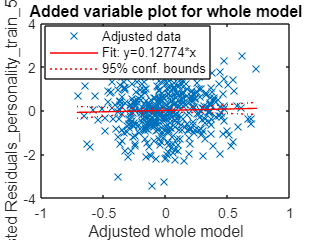

Model_Matrix = [residuals_pos_train_5_z residuals_neg_train_5_z residuals_personality_train_5_rand_z];
Model_Matrix = num2cell(Model_Matrix);
Model_Matrix_table = cell2table(Model_Matrix);
Model_Matrix_table.Properties.VariableNames = {'residuals_pos_train_5_z', 'residuals_neg_train_5_z','Residuals_personality_train_5_rand_z'};

mdl_pos_neg_bcs_train_5_rand = fitlm(Model_Matrix_table);
plot(mdl_pos_neg_bcs_train_5_rand);

**2. Predict the personality scores in the test samples**

2.1. Test Sample 1 

Get the raw residuals by subtracting the fitted values from the observed values (using regression model from above)

confounds = [Age_test_1 Gender_test_1 meanFDJenk_emotion_test_1 meanFDJenk_language_test_1 meanFDJenk_motor_test_1 meanFDJenk_relational_test_1 meanFDJenk_wm_test_1 LQ_test_1];
personality_pred_test_1 = predict(mdl_regress_train_1_personality_rand,confounds);

residuals_personality_test_1 = (Personality_test_1 - personality_pred_test_1);
residuals_personality_test_1_z = normalize(residuals_personality_test_1,"center",c_personality_train_1,"scale",s_personality_train_1);

Retrieve NMAs

Best_case_scenario_r_values_pos = Best_case_scenario_test_samples{1,1};
Best_case_scenario_r_values_neg = Best_case_scenario_test_samples{1,2};

Take the mean per subject

Positive_all = nanmean(Best_case_scenario_r_values_pos,2);
Negative_all = nanmean(Best_case_scenario_r_values_neg,2);

Regress out the confounding variables 

confounds = [Age_test_1 Gender_test_1 meanFDJenk_emotion_test_1 meanFDJenk_language_test_1 meanFDJenk_motor_test_1 meanFDJenk_relational_test_1 meanFDJenk_wm_test_1 LQ_test_1];


Positive_all_pred_test_1 = predict(mdl_regress_train_1_pos_bcs,confounds);

residuals_pos_test_1 = (Positive_all - Positive_all_pred_test_1);
residuals_pos_test_1_z = normalize(residuals_pos_test_1,"center",c_pos_NMA_train_1,"scale",s_pos_NMA_train_1);


Negative_all_pred_test_1 = predict(mdl_regress_train_1_neg_bcs,confounds);

residuals_neg_test_1 = (Negative_all - Negative_all_pred_test_1);
residuals_neg_test_1_z = normalize(residuals_neg_test_1,"center",c_neg_NMA_train_1,"scale",s_neg_NMA_train_1);

Xnew = [residuals_pos_test_1_z residuals_neg_test_1_z];
ypred1_rand = predict(mdl_pos_neg_bcs_train_1_rand,Xnew);

[r,pval] = corr(ypred1_rand,residuals_personality_test_1_z);

2.2. Test Sample 2 

Get the raw residuals by subtracting the fitted values from the observed values (using regression model from above)

confounds = [Age_test_2 Gender_test_2 meanFDJenk_emotion_test_2 meanFDJenk_language_test_2 meanFDJenk_motor_test_2 meanFDJenk_relational_test_2 meanFDJenk_wm_test_2 LQ_test_2];
personality_pred_test_2 = predict(mdl_regress_train_2_personality_rand,confounds);

residuals_personality_test_2 = (Personality_test_2 - personality_pred_test_2);
residuals_personality_test_2_z = normalize(residuals_personality_test_2,"center",c_personality_train_2,"scale",s_personality_train_2);

Retrieve NMAs

Best_case_scenario_r_values_pos = Best_case_scenario_test_samples{2,1};
Best_case_scenario_r_values_neg = Best_case_scenario_test_samples{2,2};

Take the mean per subject

Positive_all = nanmean(Best_case_scenario_r_values_pos,2);
Negative_all = nanmean(Best_case_scenario_r_values_neg,2);

Regress out the confounding variables 

confounds = [Age_test_2 Gender_test_2 meanFDJenk_emotion_test_2 meanFDJenk_language_test_2 meanFDJenk_motor_test_2 meanFDJenk_relational_test_2 meanFDJenk_wm_test_2 LQ_test_2];

Positive_all_pred_test_2 = predict(mdl_regress_train_2_pos_bcs,confounds);

residuals_pos_test_2 = (Positive_all - Positive_all_pred_test_2);
residuals_pos_test_2_z = normalize(residuals_pos_test_2,"center",c_pos_NMA_train_2,"scale",s_pos_NMA_train_2);

Negative_all_pred_test_2 = predict(mdl_regress_train_2_neg_bcs,confounds);

residuals_neg_test_2 = (Negative_all - Negative_all_pred_test_2);
residuals_neg_test_2_z = normalize(residuals_neg_test_2,"center",c_neg_NMA_train_2,"scale",s_neg_NMA_train_2);

Xnew = [residuals_pos_test_2_z residuals_neg_test_2_z];
ypred2_rand = predict(mdl_pos_neg_bcs_train_2_rand,Xnew);

[r,pval] = corr(ypred2_rand,residuals_personality_test_2_z);

2.3. Test Sample 3 

Get the raw residuals by subtracting the fitted values from the observed values (using regression model from above)

confounds = [Age_test_3 Gender_test_3 meanFDJenk_emotion_test_3 meanFDJenk_language_test_3 meanFDJenk_motor_test_3 meanFDJenk_relational_test_3 meanFDJenk_wm_test_3 LQ_test_3];
personality_pred_test_3 = predict(mdl_regress_train_3_personality_rand,confounds);

residuals_personality_test_3 = (Personality_test_3 - personality_pred_test_3);
residuals_personality_test_3_z = normalize(residuals_personality_test_3,"center",c_personality_train_3,"scale",s_personality_train_3);

Retrieve NMAs

Best_case_scenario_r_values_pos = Best_case_scenario_test_samples{3,1};
Best_case_scenario_r_values_neg = Best_case_scenario_test_samples{3,2};

Take the mean per subject

Positive_all = nanmean(Best_case_scenario_r_values_pos,2);
Negative_all = nanmean(Best_case_scenario_r_values_neg,2);

Regress out the confounding variables 

confounds = [Age_test_3 Gender_test_3 meanFDJenk_emotion_test_3 meanFDJenk_language_test_3 meanFDJenk_motor_test_3 meanFDJenk_relational_test_3 meanFDJenk_wm_test_3 LQ_test_3];

Positive_all_pred_test_3 = predict(mdl_regress_train_3_pos_bcs,confounds);

residuals_pos_test_3 = (Positive_all - Positive_all_pred_test_3);
residuals_pos_test_3_z = normalize(residuals_pos_test_3,"center",c_pos_NMA_train_3,"scale",s_pos_NMA_train_3);


Negative_all_pred_test_3 = predict(mdl_regress_train_3_neg_bcs,confounds);

residuals_neg_test_3 = (Negative_all - Negative_all_pred_test_3);
residuals_neg_test_3_z = normalize(residuals_neg_test_3,"center",c_neg_NMA_train_3,"scale",s_neg_NMA_train_3);

Xnew = [residuals_pos_test_3_z residuals_neg_test_3_z];
ypred3_rand = predict(mdl_pos_neg_bcs_train_3_rand,Xnew);

[r,pval] = corr(ypred3_rand,residuals_personality_test_3_z);

2.4. Test Sample 4 

Get the raw residuals by subtracting the fitted values from the observed values (using regression model from above)

confounds = [Age_test_4 Gender_test_4 meanFDJenk_emotion_test_4 meanFDJenk_language_test_4 meanFDJenk_motor_test_4 meanFDJenk_relational_test_4 meanFDJenk_wm_test_4 LQ_test_4];
personality_pred_test_4 = predict(mdl_regress_train_4_personality_rand,confounds);

residuals_personality_test_4 = (Personality_test_4 - personality_pred_test_4);
residuals_personality_test_4_z = normalize(residuals_personality_test_4,"center",c_personality_train_4,"scale",s_personality_train_4);

Retrieve NMAs

Best_case_scenario_r_values_pos = Best_case_scenario_test_samples{4,1};
Best_case_scenario_r_values_neg = Best_case_scenario_test_samples{4,2};

Take the mean per subject

Positive_all = nanmean(Best_case_scenario_r_values_pos,2);
Negative_all = nanmean(Best_case_scenario_r_values_neg,2);

Regress out the confounding variables 

confounds = [Age_test_4 Gender_test_4 meanFDJenk_emotion_test_4 meanFDJenk_language_test_4 meanFDJenk_motor_test_4 meanFDJenk_relational_test_4 meanFDJenk_wm_test_4 LQ_test_4];

Positive_all_pred_test_4 = predict(mdl_regress_train_4_pos_bcs,confounds);

residuals_pos_test_4 = (Positive_all - Positive_all_pred_test_4);
residuals_pos_test_4_z = normalize(residuals_pos_test_4,"center",c_pos_NMA_train_4,"scale",s_pos_NMA_train_4);

Negative_all_pred_test_4 = predict(mdl_regress_train_4_neg_bcs,confounds);

residuals_neg_test_4 = (Negative_all - Negative_all_pred_test_4);
residuals_neg_test_4_z = normalize(residuals_neg_test_4,"center",c_neg_NMA_train_4,"scale",s_neg_NMA_train_4);

Xnew = [residuals_pos_test_4_z residuals_neg_test_4_z];
ypred4_rand = predict(mdl_pos_neg_bcs_train_4_rand,Xnew);

[r,pval] = corr(ypred4_rand,residuals_personality_test_4_z);

2.5. Test Sample 5 

Get the raw residuals by subtracting the fitted values from the observed values (using regression model from above)

confounds = [Age_test_5 Gender_test_5 meanFDJenk_language_test_5 meanFDJenk_language_test_5 meanFDJenk_motor_test_5 meanFDJenk_relational_test_5 meanFDJenk_wm_test_5 LQ_test_5];
personality_pred_test_5 = predict(mdl_regress_train_5_personality_rand,confounds);

residuals_personality_test_5 = (Personality_test_5 - personality_pred_test_5);
residuals_personality_test_5_z = normalize(residuals_personality_test_5,"center",c_personality_train_5,"scale",s_personality_train_5);

Retrieve NMAs

Best_case_scenario_r_values_pos = Best_case_scenario_test_samples{5,1};
Best_case_scenario_r_values_neg = Best_case_scenario_test_samples{5,2};

Take the mean per subject

Positive_all = nanmean(Best_case_scenario_r_values_pos,2);
Negative_all = nanmean(Best_case_scenario_r_values_neg,2);

Regress out the confounding variables 

confounds = [Age_test_5 Gender_test_5 meanFDJenk_emotion_test_5 meanFDJenk_language_test_5 meanFDJenk_motor_test_5 meanFDJenk_relational_test_5 meanFDJenk_wm_test_5 LQ_test_5];

Positive_all_pred_test_5 = predict(mdl_regress_train_5_pos_bcs,confounds);

residuals_pos_test_5 = (Positive_all - Positive_all_pred_test_5);
residuals_pos_test_5_z = normalize(residuals_pos_test_5,"center",c_pos_NMA_train_5,"scale",s_pos_NMA_train_5);

Negative_all_pred_test_5 = predict(mdl_regress_train_5_neg_bcs,confounds);

residuals_neg_test_5 = (Negative_all - Negative_all_pred_test_5);
residuals_neg_test_5_z = normalize(residuals_neg_test_5,"center",c_neg_NMA_train_5,"scale",s_neg_NMA_train_5);

Xnew = [residuals_pos_test_5_z residuals_neg_test_5_z];
ypred5_rand = predict(mdl_pos_neg_bcs_train_5_rand,Xnew);

[r,pval] = corr(ypred5_rand,residuals_personality_test_5_z);

**3)  Correlate the predicted scores with the actual scores**

predicted_scores = [ypred1_rand; ypred2_rand; ypred3_rand; ypred4_rand; ypred5_rand];
actual_scores = [residuals_personality_test_1_z; residuals_personality_test_2_z; residuals_personality_test_3_z; residuals_personality_test_4_z; residuals_personality_test_5_z];

[rho_final,pval_final] = corr(predicted_scores,actual_scores);

**4) Save rho_final & pval_final for Permutation Test **

Permutation_test_all_cross_val_rounds_rho{cross_validation_round,permutation_test_round} = rho_final;
Permutation_test_all_cross_val_rounds_pval{cross_validation_round, permutation_test_round} = pval_final;

**End permutation test**

end

end

## **4. Analysis Section**

all_rhos_final_correlations = cell2mat(cross_validation_100_final_correlation_HCP(:,1))

all_rhos_final_correlations =    -0.0142
    0.0280
    0.0085
   -0.0218
    0.0596
    0.0470
    0.0036
    0.0292
    0.0469
    0.0395



all_rhos_final_correlations_z_scores = atanh(all_rhos_final_correlations);

mean_all_rhos_final_correlations_z_score = mean(all_rhos_final_correlations_z_scores);

mean_all_rhos_final_correlations_final = tanh(mean_all_rhos_final_correlations_z_score)

mean_all_rhos_final_correlations_final = 0.0184


Permutation_test_all_cross_val_rounds_rho_mat = cell2mat(Permutation_test_all_cross_val_rounds_rho);

find(Permutation_test_all_cross_val_rounds_rho_mat > mean_all_rhos_final_correlations_final)

ans =      4
     6
     9
    12
    15
    21
    22
    24
    25
    30
